clc
clear

dotq=[0.005;0;0;0;0;0];
%initial value
Qb=[0;0;0;0;0;0];
q=[0;0;0;0;0;0];
tau=150;
k1=10000;
k2=0.005;
c=0.008;
a1=50000;
a2=0.01;
lambda=0;
Es=200e3;
v=0.3;
%dt
elasticdt=0.01;
plasticdt=0.01/100;
dotlam=0;
P= [ 2/3 -1/3 -1/3 0      0      0;
     -1/3 2/3 -1/3 0      0      0;
     -1/3 -1/3 2/3  0     0      0;
     0     0     0     1   0      0;
     0     0     0     0      1  0;
     0     0     0     0      0      1];
P1=P/((1+v)*(1-2*v));
Ke=Es*P1;
Q=Ke*q;
iflag=0;

jh=1000;
for i=1:jh
    if iflag==0
        q(:,i+1)=q(:,i)+dotq*elasticdt;
        Q(:,i+1)=Q(:,i)+Ke*dotq*elasticdt;
        Qb(:,i+1)=Qb(:,i);
        lambda(:,i+1)=lambda(:,i);
        dotlam(:,i+1)=dotlam(:,i);
        tau(:,i+1)= tau(:,i);
        nr=(P*Q(:,i+1)-Qb(:,i+1))/norm(P*Q(:,i+1)-Qb(:,i+1));
        cro=dot(nr,Qb(:,i+1));
        if sqrt(3*(1-c*cro)/2)*norm(P*Q(:,i+1)-Qb(:,i+1))-tau(:,i+1)>0
            if lambda(:,i+1)<0
                iflag=0;
                q(:,i+1)=q(:,i)+dotq*elasticdt;
                Q(:,i+1)=Q(:,i)+Ke*dotq*elasticdt;
                Qb(:,i+1)=Qb(:,i);
                lambda(:,i+1)=lambda(:,i);
                dotlam(:,i+1)=dotlam(:,i);
                tau(:,i+1)= tau(:,i);
            else
                iflag=1;
                i
                syms dt
                f=Q(:,i)+Ke*dotq*dt;
                nr=(P*f-Qb(:,i+1))/norm(P*f-Qb(:,i+1));
                cro=dot(nr,Qb(:,i+1));
                f1=sqrt(3*(1-c*cro)/2)*norm(P*f-Qb(:,i+1))-tau;
                dt1=solve(f1,dt);
                dt=double(dt1);
                aa=find (dt<0);
                dt(aa)=[];
                q(:,i+1)=q(:,i)+dotq*dt;
                Q(:,i+1)=Q(:,i)+Ke*dotq*dt;
                Qb(:,i+1)=Qb(:,i);
                lambda(:,i+1)=lambda(:,i);
                dotlam(:,i+1)=dotlam(:,i);
                tau(:,i+1)= tau(:,i);
                ik=1;
            end
        end
    end
    if iflag==1 && ik==0
        q(:,i+1)=q(:,i)+dotq*plasticdt;
        nr=(P*Q(:,i)-Qb(:,i))/norm(P*Q(:,i)-Qb(:,i));
        cro=dot(nr,Qb(:,i));
        pfpq=sqrt(3/2)*((2-c*cro)*nr-c*Qb(:,i))/(2*sqrt(1-c*cro));
        n=pfpq/norm(pfpq);
        pfpa=sqrt(3/2)*((-2+c*cro)*nr+c*Qb(:,i)-c*(P*Q(:,i)-Qb(:,i)))/(2*sqrt(1-c*cro));
        aa=(pfpq-a2*norm(pfpq)*Qb(:,i))*a1;
        kp=0.5*k1*(1-k2*tau(:,i))-dot(pfpa,aa);
        lambda(:,i+1)=(dot(pfpq,Ke*dotq))/(kp+dot(pfpq,Ke*pfpq));
%       Q(:,i+1)=Q(:,i)+(Ke*dotq+lambda(:,i)*norm(pfpq)*a1*(n-a2*Qb(:,i)))*plasticdt;
        Q(:,i+1)=Q(:,i)+(Ke*dotq-lambda(:,i)*Ke*pfpq)*plasticdt;
        Qb(:,i+1)=Qb(:,i)+(lambda(:,i)*norm(pfpq)*a1*(n-a2*Qb(:,i)))*plasticdt;
        tau(:,i+1)=tau(:,i)+(0.5*lambda(:,i)*k1*(1-k2*tau(:,i)))*plasticdt;
        if lambda(:,i+1)<0
            iflag=0;
            q(:,i+1)=q(:,i)+dotq*elasticdt;
            Q(:,i+1)=Q(:,i)+Ke*dotq*elasticdt;
            Qb(:,i+1)=Qb(:,i);
            lambda(:,i+1)=lambda(:,i);
            dotlam(:,i+1)=dotlam(:,i);
            tau(:,i+1)= tau(:,i);
        end
    end
    ik=0;
end

i = 8

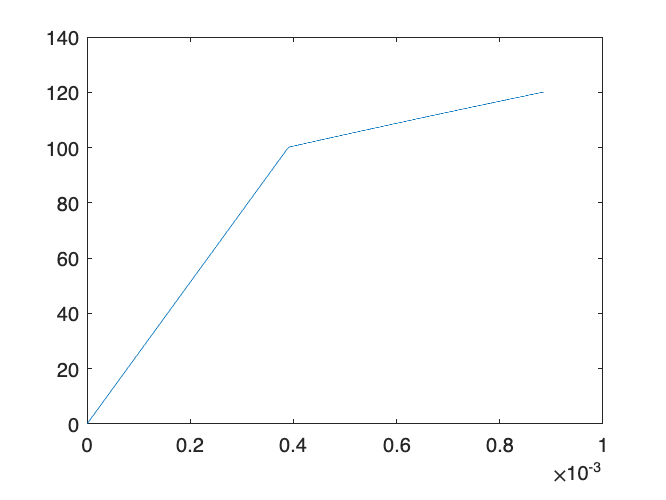

plot(q(1,1:jh),Q(1,1:jh))

for i =0:jh
nr=(P*Q(:,i+1)-Qb(:,i+1))/norm(P*Q(:,i+1)-Qb(:,i+1));
        cro=dot(nr,Qb(:,i+1));
sqrt(3*(1-c*cro)/2)*norm(P*Q(:,i+1)-Qb(:,i+1))-tau(:,i+1)
end

ans = NaN

ans = -130.7692

ans = -111.5385

ans = -92.3077

ans = -73.0769

ans = -53.8462

ans = -34.6154

ans = -15.3846

ans = -2.8422e-14

ans = 0.1923

ans = 0.1923

ans = 0.1923

ans = 0.1923

ans = 0.1923

ans = 0.1924

ans = 0.1924

ans = 0.1924

ans = 0.1924

ans = 0.1924

ans = 0.1924

ans = 0.1924

ans = 0.1925

ans = 0.1925

ans = 0.1925

ans = 0.1925

ans = 0.1925

ans = 0.1925

ans = 0.1926

ans = 0.1926

ans = 0.1926

ans = 0.1926

ans = 0.1926

ans = 0.1926

ans = 0.1926

ans = 0.1927

ans = 0.1927

ans = 0.1927

ans = 0.1927

ans = 0.1927

ans = 0.1927

ans = 0.1927

ans = 0.1928

ans = 0.1928

ans = 0.1928

ans = 0.1928

ans = 0.1928

ans = 0.1928

ans = 0.1929

ans = 0.1929

ans = 0.1929

ans = 0.1929

ans = 0.1929

ans = 0.1929

ans = 0.1929

ans = 0.1930

ans = 0.1930

ans = 0.1930

ans = 0.1930

ans = 0.1930

ans = 0.1930

ans = 0.1931

ans = 0.1931

ans = 0.1931

ans = 0.1931

ans = 0.1931

ans = 0.1931

ans = 0.1931

ans = 0.1932

ans = 0.1932

ans = 0.1932

ans = 0.1932

ans = 0.1932

ans = 0.1932

ans = 0.1932

ans = 0.1933

ans = 0.1933

ans = 0.1933

ans = 0.1933

ans = 0.1933

ans = 0.1933

ans = 0.1934

ans = 0.1934

ans = 0.1934

ans = 0.1934

ans = 0.1934

ans = 0.1934

ans = 0.1934

ans = 0.1935

ans = 0.1935

ans = 0.1935

ans = 0.1935

ans = 0.1935

ans = 0.1935

ans = 0.1935

ans = 0.1936

ans = 0.1936

ans = 0.1936

ans = 0.1936

ans = 0.1936

ans = 0.1936

ans = 0.1937

ans = 0.1937

ans = 0.1937

ans = 0.1937

ans = 0.1937

ans = 0.1937

ans = 0.1937

ans = 0.1938

ans = 0.1938

ans = 0.1938

ans = 0.1938

ans = 0.1938

ans = 0.1938

ans = 0.1938

ans = 0.1939

ans = 0.1939

ans = 0.1939

ans = 0.1939

ans = 0.1939

ans = 0.1939

ans = 0.1940

ans = 0.1940

ans = 0.1940

ans = 0.1940

ans = 0.1940

ans = 0.1940

ans = 0.1940

ans = 0.1941

ans = 0.1941

ans = 0.1941

ans = 0.1941

ans = 0.1941

ans = 0.1941

ans = 0.1941

ans = 0.1942

ans = 0.1942

ans = 0.1942

ans = 0.1942

ans = 0.1942

ans = 0.1942

ans = 0.1943

ans = 0.1943

ans = 0.1943

ans = 0.1943

ans = 0.1943

ans = 0.1943

ans = 0.1943

ans = 0.1944

ans = 0.1944

ans = 0.1944

ans = 0.1944

ans = 0.1944

ans = 0.1944

ans = 0.1944

ans = 0.1945

ans = 0.1945

ans = 0.1945

ans = 0.1945

ans = 0.1945

ans = 0.1945

ans = 0.1946

ans = 0.1946

ans = 0.1946

ans = 0.1946

ans = 0.1946

ans = 0.1946

ans = 0.1946

ans = 0.1947

ans = 0.1947

ans = 0.1947

ans = 0.1947

ans = 0.1947

ans = 0.1947

ans = 0.1947

ans = 0.1948

ans = 0.1948

ans = 0.1948

ans = 0.1948

ans = 0.1948

ans = 0.1948

ans = 0.1949

ans = 0.1949

ans = 0.1949

ans = 0.1949

ans = 0.1949

ans = 0.1949

ans = 0.1949

ans = 0.1950

ans = 0.1950

ans = 0.1950

ans = 0.1950

ans = 0.1950

ans = 0.1950

ans = 0.1950

ans = 0.1951

ans = 0.1951

ans = 0.1951

ans = 0.1951

ans = 0.1951

ans = 0.1951

ans = 0.1952

ans = 0.1952

ans = 0.1952

ans = 0.1952

ans = 0.1952

ans = 0.1952

ans = 0.1952

ans = 0.1953

ans = 0.1953

ans = 0.1953

ans = 0.1953

ans = 0.1953

ans = 0.1953

ans = 0.1953

ans = 0.1954

ans = 0.1954

ans = 0.1954

ans = 0.1954

ans = 0.1954

ans = 0.1954

ans = 0.1954

ans = 0.1955

ans = 0.1955

ans = 0.1955

ans = 0.1955

ans = 0.1955

ans = 0.1955

ans = 0.1956

ans = 0.1956

ans = 0.1956

ans = 0.1956

ans = 0.1956

ans = 0.1956

ans = 0.1956

ans = 0.1957

ans = 0.1957

ans = 0.1957

ans = 0.1957

ans = 0.1957

ans = 0.1957

ans = 0.1957

ans = 0.1958

ans = 0.1958

ans = 0.1958

ans = 0.1958

ans = 0.1958

ans = 0.1958

ans = 0.1958

ans = 0.1959

ans = 0.1959

ans = 0.1959

ans = 0.1959

ans = 0.1959

ans = 0.1959

ans = 0.1960

ans = 0.1960

ans = 0.1960

ans = 0.1960

ans = 0.1960

ans = 0.1960

ans = 0.1960

ans = 0.1961

ans = 0.1961

ans = 0.1961

ans = 0.1961

ans = 0.1961

ans = 0.1961

ans = 0.1961

ans = 0.1962

ans = 0.1962

ans = 0.1962

ans = 0.1962

ans = 0.1962

ans = 0.1962

ans = 0.1962

ans = 0.1963

ans = 0.1963

ans = 0.1963

ans = 0.1963

ans = 0.1963

ans = 0.1963

ans = 0.1963

ans = 0.1964

ans = 0.1964

ans = 0.1964

ans = 0.1964

ans = 0.1964

ans = 0.1964

ans = 0.1965

ans = 0.1965

ans = 0.1965

ans = 0.1965

ans = 0.1965

ans = 0.1965

ans = 0.1965

ans = 0.1966

ans = 0.1966

ans = 0.1966

ans = 0.1966

ans = 0.1966

ans = 0.1966

ans = 0.1966

ans = 0.1967

ans = 0.1967

ans = 0.1967

ans = 0.1967

ans = 0.1967

ans = 0.1967

ans = 0.1967

ans = 0.1968

ans = 0.1968

ans = 0.1968

ans = 0.1968

ans = 0.1968

ans = 0.1968

ans = 0.1968

ans = 0.1969

ans = 0.1969

ans = 0.1969

ans = 0.1969

ans = 0.1969

ans = 0.1969

ans = 0.1970

ans = 0.1970

ans = 0.1970

ans = 0.1970

ans = 0.1970

ans = 0.1970

ans = 0.1970

ans = 0.1971

ans = 0.1971

ans = 0.1971

ans = 0.1971

ans = 0.1971

ans = 0.1971

ans = 0.1971

ans = 0.1972

ans = 0.1972

ans = 0.1972

ans = 0.1972

ans = 0.1972

ans = 0.1972

ans = 0.1972

ans = 0.1973

ans = 0.1973

ans = 0.1973

ans = 0.1973

ans = 0.1973

ans = 0.1973

ans = 0.1973

ans = 0.1974

ans = 0.1974

ans = 0.1974

ans = 0.1974

ans = 0.1974

ans = 0.1974

ans = 0.1974

ans = 0.1975

ans = 0.1975

ans = 0.1975

ans = 0.1975

ans = 0.1975

ans = 0.1975

ans = 0.1976

ans = 0.1976

ans = 0.1976

ans = 0.1976

ans = 0.1976

ans = 0.1976

ans = 0.1976

ans = 0.1977

ans = 0.1977

ans = 0.1977

ans = 0.1977

ans = 0.1977

ans = 0.1977

ans = 0.1977

ans = 0.1978

ans = 0.1978

ans = 0.1978

ans = 0.1978

ans = 0.1978

ans = 0.1978

ans = 0.1978

ans = 0.1979

ans = 0.1979

ans = 0.1979

ans = 0.1979

ans = 0.1979

ans = 0.1979

ans = 0.1979

ans = 0.1980

ans = 0.1980

ans = 0.1980

ans = 0.1980

ans = 0.1980

ans = 0.1980

ans = 0.1980

ans = 0.1981

ans = 0.1981

ans = 0.1981

ans = 0.1981

ans = 0.1981

ans = 0.1981

ans = 0.1981

ans = 0.1982

ans = 0.1982

ans = 0.1982

ans = 0.1982

ans = 0.1982

ans = 0.1982

ans = 0.1982

ans = 0.1983

ans = 0.1983

ans = 0.1983

ans = 0.1983

ans = 0.1983

ans = 0.1983

ans = 0.1984

ans = 0.1984

ans = 0.1984

ans = 0.1984

ans = 0.1984

ans = 0.1984

ans = 0.1984

ans = 0.1985

ans = 0.1985

ans = 0.1985

ans = 0.1985

ans = 0.1985

ans = 0.1985

ans = 0.1985

ans = 0.1986

ans = 0.1986

ans = 0.1986

ans = 0.1986

ans = 0.1986

ans = 0.1986

ans = 0.1986

ans = 0.1987

ans = 0.1987

ans = 0.1987

ans = 0.1987

ans = 0.1987

ans = 0.1987

ans = 0.1987

ans = 0.1988

ans = 0.1988

ans = 0.1988

ans = 0.1988

ans = 0.1988

ans = 0.1988

ans = 0.1988

ans = 0.1989

ans = 0.1989

ans = 0.1989

ans = 0.1989

ans = 0.1989

ans = 0.1989

ans = 0.1989

ans = 0.1990

ans = 0.1990

ans = 0.1990

ans = 0.1990

ans = 0.1990

ans = 0.1990

ans = 0.1990

ans = 0.1991

ans = 0.1991

ans = 0.1991

ans = 0.1991

ans = 0.1991

ans = 0.1991

ans = 0.1991

ans = 0.1992

ans = 0.1992

ans = 0.1992

ans = 0.1992

ans = 0.1992

ans = 0.1992

ans = 0.1992

ans = 0.1993

ans = 0.1993

ans = 0.1993

ans = 0.1993

ans = 0.1993

ans = 0.1993

ans = 0.1993

ans = 0.1994

ans = 0.1994

ans = 0.1994

ans = 0.1994

ans = 0.1994

ans = 0.1994

ans = 0.1994

ans = 0.1995

ans = 0.1995

ans = 0.1995

ans = 0.1995

ans = 0.1995

ans = 0.1995

ans = 0.1995

ans = 0.1996

ans = 0.1996

ans = 0.1996

ans = 0.1996

ans = 0.1996

ans = 0.1996

ans = 0.1996

ans = 0.1997

ans = 0.1997

ans = 0.1997

ans = 0.1997

ans = 0.1997

ans = 0.1997

ans = 0.1997

ans = 0.1998

ans = 0.1998

ans = 0.1998

ans = 0.1998

ans = 0.1998

ans = 0.1998

ans = 0.1998

ans = 0.1999

ans = 0.1999

ans = 0.1999

ans = 0.1999

ans = 0.1999

ans = 0.1999

ans = 0.1999

ans = 0.2000

ans = 0.2000

ans = 0.2000

ans = 0.2000

ans = 0.2000

ans = 0.2000

ans = 0.2000

ans = 0.2001

ans = 0.2001

ans = 0.2001

ans = 0.2001

ans = 0.2001

ans = 0.2001

ans = 0.2001

ans = 0.2002

ans = 0.2002

ans = 0.2002

ans = 0.2002

ans = 0.2002

ans = 0.2002

ans = 0.2002

ans = 0.2003

ans = 0.2003

ans = 0.2003

ans = 0.2003

ans = 0.2003

ans = 0.2003

ans = 0.2003

ans = 0.2004

ans = 0.2004

ans = 0.2004

ans = 0.2004

ans = 0.2004

ans = 0.2004

ans = 0.2004

ans = 0.2005

ans = 0.2005

ans = 0.2005

ans = 0.2005

ans = 0.2005

ans = 0.2005

ans = 0.2005

ans = 0.2006

ans = 0.2006

ans = 0.2006

ans = 0.2006

ans = 0.2006

ans = 0.2006

ans = 0.2006

ans = 0.2007

ans = 0.2007

ans = 0.2007

ans = 0.2007

ans = 0.2007

ans = 0.2007

ans = 0.2007

ans = 0.2008

ans = 0.2008

ans = 0.2008

ans = 0.2008

ans = 0.2008

ans = 0.2008

ans = 0.2008

ans = 0.2009

ans = 0.2009

ans = 0.2009

ans = 0.2009

ans = 0.2009

ans = 0.2009

ans = 0.2009

ans = 0.2010

ans = 0.2010

ans = 0.2010

ans = 0.2010

ans = 0.2010

ans = 0.2010

ans = 0.2010

ans = 0.2011

ans = 0.2011

ans = 0.2011

ans = 0.2011

ans = 0.2011

ans = 0.2011

ans = 0.2011

ans = 0.2012

ans = 0.2012

ans = 0.2012

ans = 0.2012

ans = 0.2012

ans = 0.2012

ans = 0.2012

ans = 0.2013

ans = 0.2013

ans = 0.2013

ans = 0.2013

ans = 0.2013

ans = 0.2013

ans = 0.2013

ans = 0.2014

ans = 0.2014

ans = 0.2014

ans = 0.2014

ans = 0.2014

ans = 0.2014

ans = 0.2014

ans = 0.2015

ans = 0.2015

ans = 0.2015

ans = 0.2015

ans = 0.2015

ans = 0.2015

ans = 0.2015

ans = 0.2016

ans = 0.2016

ans = 0.2016

ans = 0.2016

ans = 0.2016

ans = 0.2016

ans = 0.2016

ans = 0.2017

ans = 0.2017

ans = 0.2017

ans = 0.2017

ans = 0.2017

ans = 0.2017

ans = 0.2017

ans = 0.2018

ans = 0.2018

ans = 0.2018

ans = 0.2018

ans = 0.2018

ans = 0.2018

ans = 0.2018

ans = 0.2019

ans = 0.2019

ans = 0.2019

ans = 0.2019

ans = 0.2019

ans = 0.2019

ans = 0.2019

ans = 0.2020

ans = 0.2020

ans = 0.2020

ans = 0.2020

ans = 0.2020

ans = 0.2020

ans = 0.2020

ans = 0.2020

ans = 0.2021

ans = 0.2021

ans = 0.2021

ans = 0.2021

ans = 0.2021

ans = 0.2021

ans = 0.2021

ans = 0.2022

ans = 0.2022

ans = 0.2022

ans = 0.2022

ans = 0.2022

ans = 0.2022

ans = 0.2022

ans = 0.2023

ans = 0.2023

ans = 0.2023

ans = 0.2023

ans = 0.2023

ans = 0.2023

ans = 0.2023

ans = 0.2024

ans = 0.2024

ans = 0.2024

ans = 0.2024

ans = 0.2024

ans = 0.2024

ans = 0.2024

ans = 0.2025

ans = 0.2025

ans = 0.2025

ans = 0.2025

ans = 0.2025

ans = 0.2025

ans = 0.2025

ans = 0.2026

ans = 0.2026

ans = 0.2026

ans = 0.2026

ans = 0.2026

ans = 0.2026

ans = 0.2026

ans = 0.2027

ans = 0.2027

ans = 0.2027

ans = 0.2027

ans = 0.2027

ans = 0.2027

ans = 0.2027

ans = 0.2027

ans = 0.2028

ans = 0.2028

ans = 0.2028

ans = 0.2028

ans = 0.2028

ans = 0.2028

ans = 0.2028

ans = 0.2029

ans = 0.2029

ans = 0.2029

ans = 0.2029

ans = 0.2029

ans = 0.2029

ans = 0.2029

ans = 0.2030

ans = 0.2030

ans = 0.2030

ans = 0.2030

ans = 0.2030

ans = 0.2030

ans = 0.2030

ans = 0.2031

ans = 0.2031

ans = 0.2031

ans = 0.2031

ans = 0.2031

ans = 0.2031

ans = 0.2031

ans = 0.2032

ans = 0.2032

ans = 0.2032

ans = 0.2032

ans = 0.2032

ans = 0.2032

ans = 0.2032

ans = 0.2033

ans = 0.2033

ans = 0.2033

ans = 0.2033

ans = 0.2033

ans = 0.2033

ans = 0.2033

ans = 0.2033

ans = 0.2034

ans = 0.2034

ans = 0.2034

ans = 0.2034

ans = 0.2034

ans = 0.2034

ans = 0.2034

ans = 0.2035

ans = 0.2035

ans = 0.2035

ans = 0.2035

ans = 0.2035

ans = 0.2035

ans = 0.2035

ans = 0.2036

ans = 0.2036

ans = 0.2036

ans = 0.2036

ans = 0.2036

ans = 0.2036

ans = 0.2036

ans = 0.2037

ans = 0.2037

ans = 0.2037

ans = 0.2037

ans = 0.2037

ans = 0.2037

ans = 0.2037

ans = 0.2038

ans = 0.2038

ans = 0.2038

ans = 0.2038

ans = 0.2038

ans = 0.2038

ans = 0.2038

ans = 0.2038

ans = 0.2039

ans = 0.2039

ans = 0.2039

ans = 0.2039

ans = 0.2039

ans = 0.2039

ans = 0.2039

ans = 0.2040

ans = 0.2040

ans = 0.2040

ans = 0.2040

ans = 0.2040

ans = 0.2040

ans = 0.2040

ans = 0.2041

ans = 0.2041

ans = 0.2041

ans = 0.2041

ans = 0.2041

ans = 0.2041

ans = 0.2041

ans = 0.2042

ans = 0.2042

ans = 0.2042

ans = 0.2042

ans = 0.2042

ans = 0.2042

ans = 0.2042

ans = 0.2043

ans = 0.2043

ans = 0.2043

ans = 0.2043

ans = 0.2043

ans = 0.2043

ans = 0.2043

ans = 0.2043

ans = 0.2044

ans = 0.2044

ans = 0.2044

ans = 0.2044

ans = 0.2044

ans = 0.2044

ans = 0.2044

ans = 0.2045

ans = 0.2045

ans = 0.2045

ans = 0.2045

ans = 0.2045

ans = 0.2045

ans = 0.2045

ans = 0.2046

ans = 0.2046

ans = 0.2046

ans = 0.2046

ans = 0.2046

ans = 0.2046

ans = 0.2046

ans = 0.2046

ans = 0.2047

ans = 0.2047

ans = 0.2047

ans = 0.2047

ans = 0.2047

ans = 0.2047

ans = 0.2047

ans = 0.2048

ans = 0.2048

ans = 0.2048

ans = 0.2048

ans = 0.2048

ans = 0.2048

ans = 0.2048

ans = 0.2049

ans = 0.2049

ans = 0.2049

ans = 0.2049

ans = 0.2049

ans = 0.2049

ans = 0.2049

ans = 0.2050

ans = 0.2050

ans = 0.2050

ans = 0.2050

ans = 0.2050

ans = 0.2050

ans = 0.2050

ans = 0.2050

ans = 0.2051

ans = 0.2051

ans = 0.2051

ans = 0.2051

ans = 0.2051

ans = 0.2051

ans = 0.2051

ans = 0.2052

ans = 0.2052

ans = 0.2052

ans = 0.2052

ans = 0.2052

ans = 0.2052

ans = 0.2052

ans = 0.2053

ans = 0.2053

ans = 0.2053

ans = 0.2053

ans = 0.2053

ans = 0.2053

ans = 0.2053

ans = 0.2053

ans = 0.2054

ans = 0.2054

ans = 0.2054

ans = 0.2054

ans = 0.2054

ans = 0.2054

ans = 0.2054

ans = 0.2055

ans = 0.2055

ans = 0.2055

ans = 0.2055

ans = 0.2055

ans = 0.2055

ans = 0.2055

ans = 0.2056

ans = 0.2056

ans = 0.2056

ans = 0.2056

ans = 0.2056

ans = 0.2056

ans = 0.2056

ans = 0.2056

ans = 0.2057

ans = 0.2057

ans = 0.2057

ans = 0.2057

ans = 0.2057

ans = 0.2057

ans = 0.2057

ans = 0.2058

ans = 0.2058

ans = 0.2058

ans = 0.2058

ans = 0.2058

ans = 0.2058

ans = 0.2058

ans = 0.2059

ans = 0.2059

ans = 0.2059

ans = 0.2059

ans = 0.2059

ans = 0.2059

ans = 0.2059

ans = 0.2059

ans = 0.2060

ans = 0.2060

ans = 0.2060

ans = 0.2060

ans = 0.2060

ans = 0.2060

ans = 0.2060

ans = 0.2061

ans = 0.2061

ans = 0.2061

ans = 0.2061

ans = 0.2061

ans = 0.2061

ans = 0.2061

ans = 0.2062

ans = 0.2062

ans = 0.2062

ans = 0.2062

ans = 0.2062

ans = 0.2062

ans = 0.2062

ans = 0.2062

ans = 0.2063

ans = 0.2063

ans = 0.2063

ans = 0.2063

ans = 0.2063

ans = 0.2063

ans = 0.2063

ans = 0.2064

ans = 0.2064

ans = 0.2064

ans = 0.2064

ans = 0.2064

ans = 0.2064

ans = 0.2064

ans = 0.2065

ans = 0.2065

ans = 0.2065

ans = 0.2065

ans = 0.2065